# let's look at some convoluted graphics functions

## Preprocessing

Set save path and make up some data. Fetch graphics scrut from setup_graphics().


path_save = 'C:\Users\everett\Pictures';



## Plot first

Plot the stuff you want. Always name figures. Limits and labelling can be set here as well, but most graphical parameters can be defined in a fucntional manner.

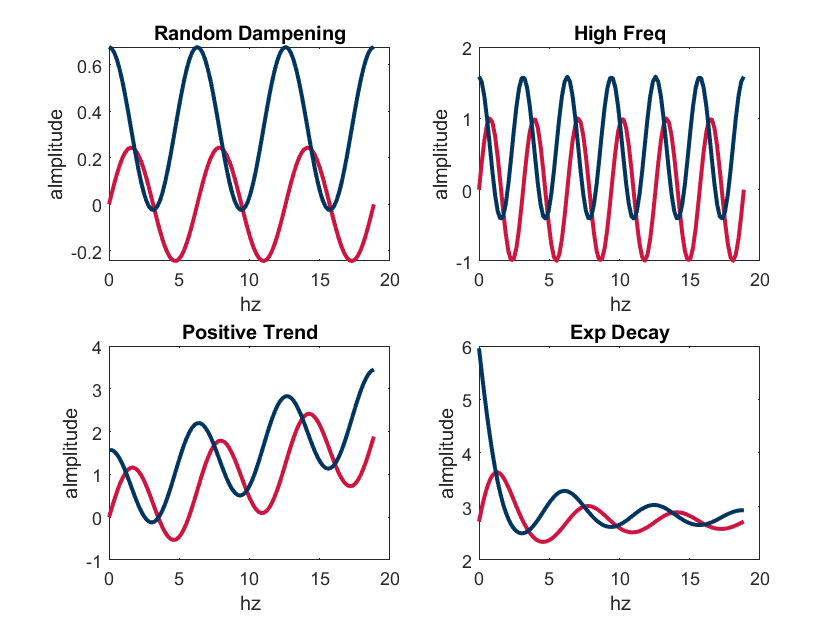

fh =   Figure (1: sin wave transofmrations) with properties:

      Number: 1
        Name: 'sin wave transofmrations'
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fh = plot_example()

wow it looks like garbage

## Make figure text lower case

Simple, makes everything lower case. This ensures consistensy, but could be annoying if you want upper-case accronyms. There might be some exceptions I haven't run into (e.g. character x-tick labels).

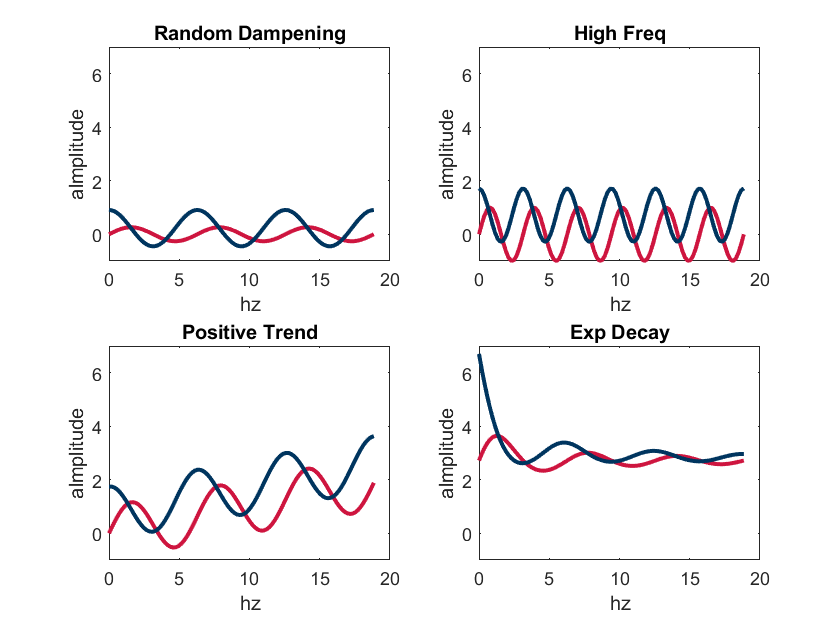

kill
gh = gfx2('fh',plot_example());
gh.share_lims('all')

Here we share lims, but only along rows, so axes in each row have the same y-limits

We also remove inner xlabels, yabels, and ticks, since these are the sam for all plots

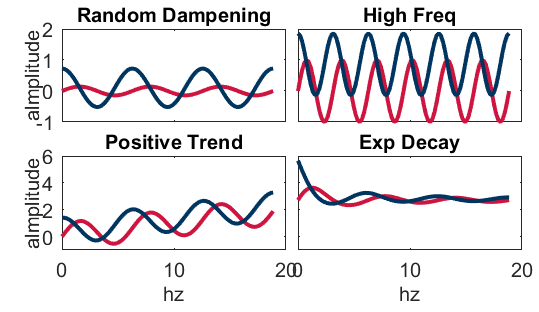

ans =   Figure (1: sin wave transofmrations) with properties:

      Number: 1
        Name: 'sin wave transofmrations'
       Color: [1 1 1]
    Position: [0 0 9.5000 5.5000]
       Units: 'centimeters'

  Show all properties


gh = gfx2('fh',plot_example());
gh.share_lims('rowwise')
gh.remove_inner({'xlabels','xticks','ylabels','yticks'})
gh.apply([gh.width.page/2, gh.height.page/4],'margins',[0.1,0.1,0.1,0.5],'frame',[1,0.2,1,0])

## Fix the margins between subplots

Accepts four arguments, margins and a buffer space for legend at the bottom. Could be easily adapted to have buffer space on the side.

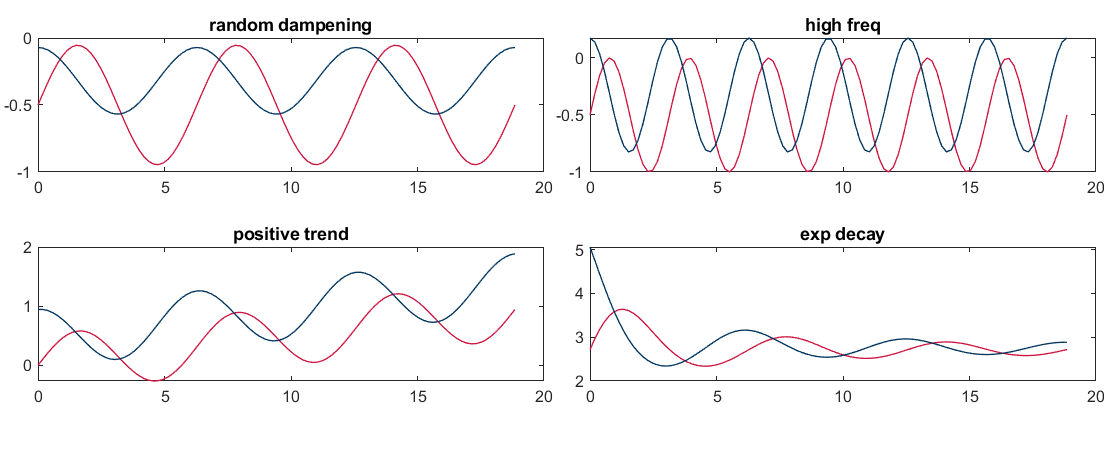

margin_right = 1;
margin_left = 0.2;
margin_bottom = 1;
margin_top = 1;
margin_legend = 1;

fix_margins(margin_right,margin_left,...
    margin_bottom,margin_top,...
    margin_legend)

## Add a legend, centered at the bottom of the plot

What it says, adds a legend at the bottom left, right, or center. Adds a border, but could be turned off. Should be done outside a subplot loop, as it only adds a legend to the most recent subplot.

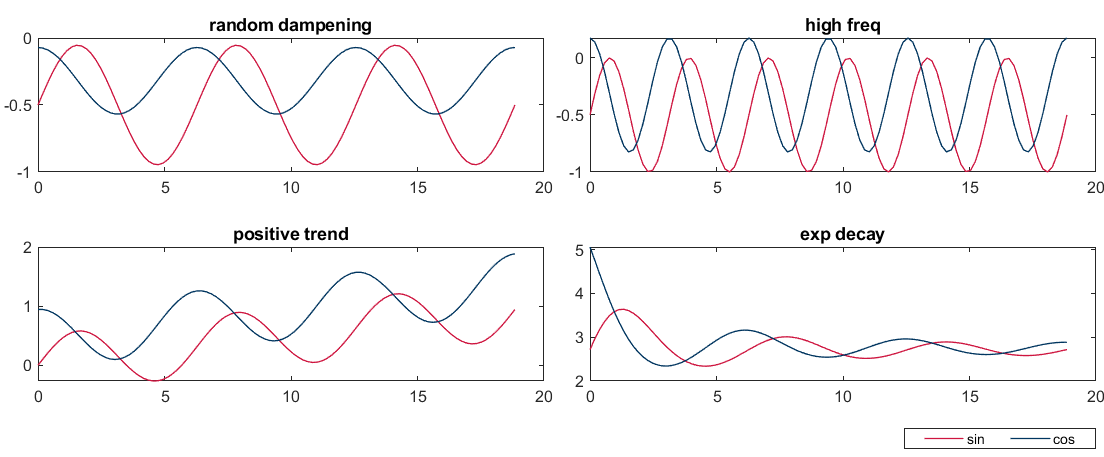

lh = legend({'sin','cos'});
fix_legend(lh,'right')

## Make uniform limits across subplots

Finds the largest limits across subplots and applies to all subplots. This is very nice for making comparisons between subplots. Option to have neg-limit = pos-limit, and add a buffer ratio so the data doesn't bottom out against the axis border.

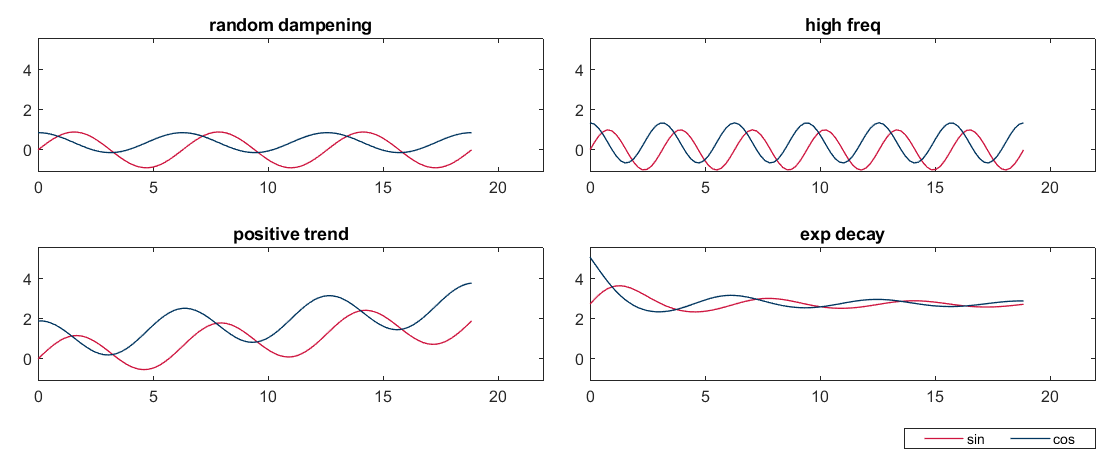

fh = apply_sqlims(gcf,'buff_ratio',1.1);

## Insert a zoom window

Adds a zoom window to subplots. This script is pretty sloppy, and could easily be improved, or adapted to have a non-uniform zoom window across subplots. For now it's good enough...

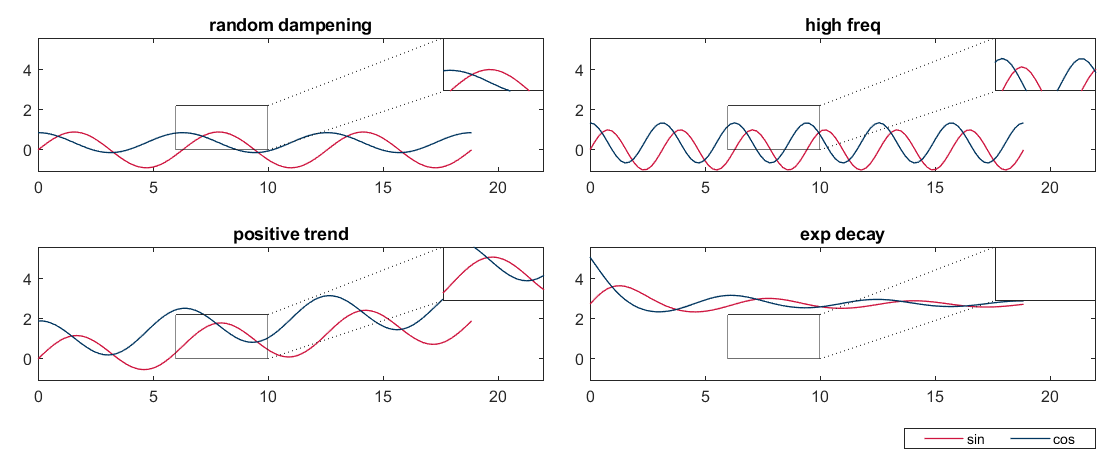

extent_horz = [6 10];
extent_vert = [0 2.2];
ratio = [0.2,0.4];
insert_zoombox(gcf,extent_horz,extent_vert,ratio)